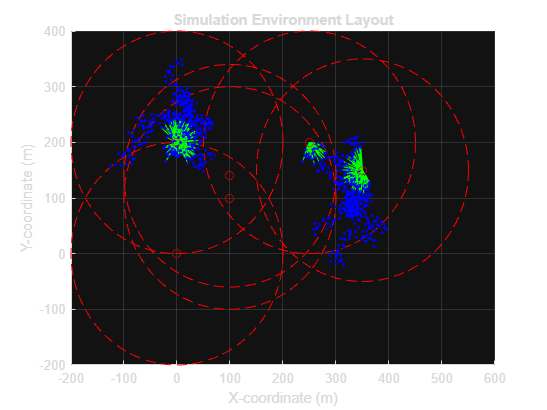

% Read the CSV file with preserved variable names
mobileDeviceData = readtable('E:\OneDrive\Desktop\KLE TECH\VI SEM\MP2\Project Files\aplocations_meter.csv', 'VariableNamingRule', 'preserve');

% Extract the first 50 rows from the table
mobileDeviceData = mobileDeviceData(1:50, :);

% Extract x and y coordinates for mobile devices
x_coordinates_mobile = mobileDeviceData.('x (in meter)');
y_coordinates_mobile = mobileDeviceData.('y (in meter)');

% Filter points where the values are less than 400 and greater than 0
filtered_indices = find(x_coordinates_mobile < 400 & y_coordinates_mobile < 400 & x_coordinates_mobile > 0 & y_coordinates_mobile > 0);
x_coordinates_mobile = x_coordinates_mobile(filtered_indices);
y_coordinates_mobile = y_coordinates_mobile(filtered_indices);

% Define the number of mobile devices
numMobileDevices = length(x_coordinates_mobile);

% Define the positions of 6 base stations manually
baseStationPositions = [
    0,0;
    100,140;
    250,200;
    0,200;
    100,100;
    350,150;
];

% Define the number of base stations
numBaseStations = size(baseStationPositions,1);

% Generate mobile device locations from filtered coordinates
mobileDeviceLocations = [x_coordinates_mobile, y_coordinates_mobile];

% Visualize the layout
figure;
set(gcf, 'Color', 'w'); % Set figure background to white
scatter(baseStationPositions(:,1), baseStationPositions(:,2), 'ro', 'DisplayName', 'Base Stations');
hold on;
scatter(mobileDeviceLocations(:,1), mobileDeviceLocations(:,2), 'b.', 'DisplayName', 'Mobile Devices');
xlabel('X-coordinate (m)');
ylabel('Y-coordinate (m)');
title('Simulation Environment Layout');
%legend;

% Step 3: Base Station Parameters (including beamforming)
% -------------------------------------------------------
baseStationParams = struct('transmitPower', 30, ...
                           'antennaGain', 40, ...
                           'frequency', 28e9, ...
                           'MIMO', true, ...
                           'beamformingWeights', generateBeamformingWeights(4), ... % 4 antennas
                           'coverageRadius', 200); % Example coverage radius

% Calculate coverage radius for base stations
coverageRadius = baseStationParams.coverageRadius;

% Define coverage areas for base stations
baseStationCoverage = defineCoverageAreas(baseStationPositions, coverageRadius);

% Visualize coverage areas
for i = 1:length(baseStationCoverage)
    plotCircle(baseStationCoverage(i).center, baseStationCoverage(i).radius);
end

% Step 6: Simulate Mobility with Beamforming
% ------------------------------------------
numSteps = 50; % Number of simulation steps

% Simulate mobility of mobile devices
for t = 1:numSteps
    % Update positions of mobile devices
    stepSize = 10; % Step size in meters
    directions = rand(numMobileDevices, 1) * 2 * pi; % Random directions
    mobileDeviceLocations(:, 1) = mobileDeviceLocations(:, 1) + stepSize * cos(directions);
    mobileDeviceLocations(:, 2) = mobileDeviceLocations(:, 2) + stepSize * sin(directions);
    
    % Perform handover and dual connectivity
    for i = 1:numMobileDevices
        devicePos = mobileDeviceLocations(i, :);
        newBS = performHandover(devicePos, baseStationPositions, baseStationParams);
        [primaryBS, secondaryBS] = performDualConnectivity(devicePos, baseStationPositions, baseStationParams);
        
        % Update connection status (for visualization purposes)
        % For example, you can plot the lines indicating connections
        if primaryBS > 0
            plot([devicePos(1), baseStationPositions(primaryBS, 1)], ...
                 [devicePos(2), baseStationPositions(primaryBS, 2)], 'g-');
        end
        if secondaryBS > 0
            plot([devicePos(1), baseStationPositions(secondaryBS, 1)], ...
                 [devicePos(2), baseStationPositions(secondaryBS, 2)], 'b--');
        end
    end
    
    % Update the plot
    scatter(baseStationPositions(:,1), baseStationPositions(:,2), 'ro');
    hold on;
    scatter(mobileDeviceLocations(:,1), mobileDeviceLocations(:,2), 'b.');
    xlabel('X-coordinate (m)');
    ylabel('Y-coordinate (m)');
    title('Simulation Environment Layout');
    drawnow;
    grid on;
end


% Function to generate beamforming weights (random for demonstration)

function weights = generateBeamformingWeights(numAntennas)
    % Generate random complex weights (for demonstration)
    weights = rand(numAntennas, 1) .* exp(1i * rand(numAntennas, 1) * 2 * pi);
end

% Update transmit power calculation considering beamforming gain
function transmitPowerWatts = calculateTransmitPower(baseStationParams)
    % Adjust transmit power considering beamforming gain
    transmitPowerWatts = 10^((baseStationParams.transmitPower - 30) / 10) * abs(mean(baseStationParams.beamformingWeights))^2;
end

% Update Handover Algorithm considering beamforming gain
function newBS = performHandover(devicePos, baseStationPositions, baseStationParams)
    numBaseStations = size(baseStationPositions, 1);
    % Consider beamforming gain and directionality when calculating distances
    distances = zeros(numBaseStations, 1);
    for i = 1:numBaseStations
        distance = norm(devicePos - baseStationPositions(i, :));
        % Adjust distance based on beamforming gain
        adjustedDistance = distance / abs(mean(baseStationParams.beamformingWeights));
        distances(i) = adjustedDistance;
    end
    % Select the base station with the shortest adjusted distance
    [minDistance, newBS] = min(distances);
    % Check if the new base station is within its coverage radius
    if minDistance > baseStationParams.coverageRadius
        newBS = -1; % No handover if no base station is within range
    end
end

% Update Dual Connectivity considering beamforming gain
function [primaryBS, secondaryBS] = performDualConnectivity(devicePos, baseStationPositions, baseStationParams)
    numBaseStations = size(baseStationPositions, 1);
    % Consider beamforming gain and directionality when determining primary and secondary connections
    distances = zeros(numBaseStations, 1);
    for i = 1:numBaseStations
        distance = norm(devicePos - baseStationPositions(i, :));
        % Adjust distance based on beamforming gain
        adjustedDistance = distance / abs(mean(baseStationParams.beamformingWeights));
        distances(i) = adjustedDistance;
    end
    % Sort distances and select primary and secondary connections
    [sortedDistances, sortedIndices] = sort(distances);
    primaryBS = -1;
    secondaryBS = -1;
    if sortedDistances(1) < baseStationParams.coverageRadius
        primaryBS = sortedIndices(1);
    end
    if length(sortedDistances) > 1 && sortedDistances(2) < baseStationParams.coverageRadius
        secondaryBS = sortedIndices(2);
    end
end

% Define coverage areas for base stations
function coverage = defineCoverageAreas(baseStationLocations, coverageRadius)
    numBaseStations = size(baseStationLocations, 1);
    coverage(numBaseStations) = struct('center', [], 'radius', []);
    for i = 1:numBaseStations
        coverage(i).center = baseStationLocations(i, :);
        coverage(i).radius = coverageRadius;
    end
end

% Plot circle function for visualizing coverage areas
function plotCircle(center, radius)
    theta = linspace(0, 2*pi, 100);
    x = center(1) + radius * cos(theta);
    y = center(2) + radius * sin(theta);
    plot(x, y, 'r--');
end
